

% Define initial state
% A population of 100 persons, 99 susceptible and 1 infectious
s_0 = 99;
i_0 = 1;
r_0 = 0;

% Let's interpret t to be Weeks; thus
% Infection rate: Each infected person has a chance to infect 1 susceptible
%                 person out of 50
% Recovery rate: The infection lasts 4 weeks before recovery
r_time = 4;
s_time = 12;
beta = 1 / 50;
num_week = 40;
% Run simulation
[S, I, R, W] = simulation_copy(s_0, i_0, r_0, beta, num_week, r_time, s_time)

infected_list =     1.0000    1.9800    5.7824   15.9892   37.2504   37.9981         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


S =    99.0000   97.0200   91.2376   75.2484   37.9981         0         0         0         0         0         0         0         0         0         0         0    1.0000    2.9800    8.7624   24.7516   62.0019  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000


I =     1.0000    2.9800    8.7624   24.7516   61.0019   97.0200   91.2376   75.2484   37.9981         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


R =          0         0         0         0    1.0000    2.9800    8.7624   24.7516   62.0019  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000   99.0000   97.0200   91.2376   75.2484   37.9981         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


W =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40


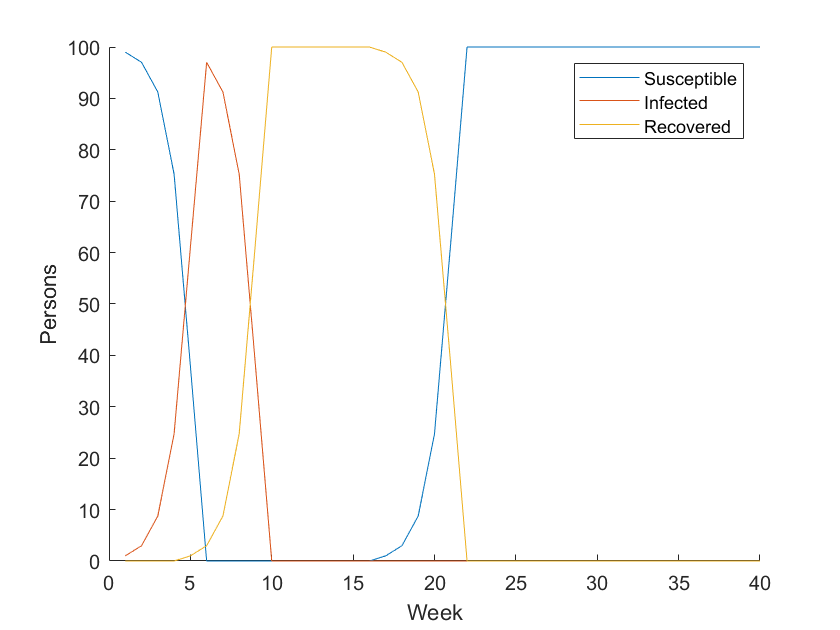


% Plot
figure(1); clf; hold on;
plot(W, S); label1 = "Susceptible";
plot(W, I); label2 = "Infected";
plot(W, R); label3 = "Recovered";

xlabel("Week")
ylabel("Persons")
legend({label1, label2, label3})

%(s, i, r, beta, r_time, s_time, infected_list, step)